## Example using surface elevation

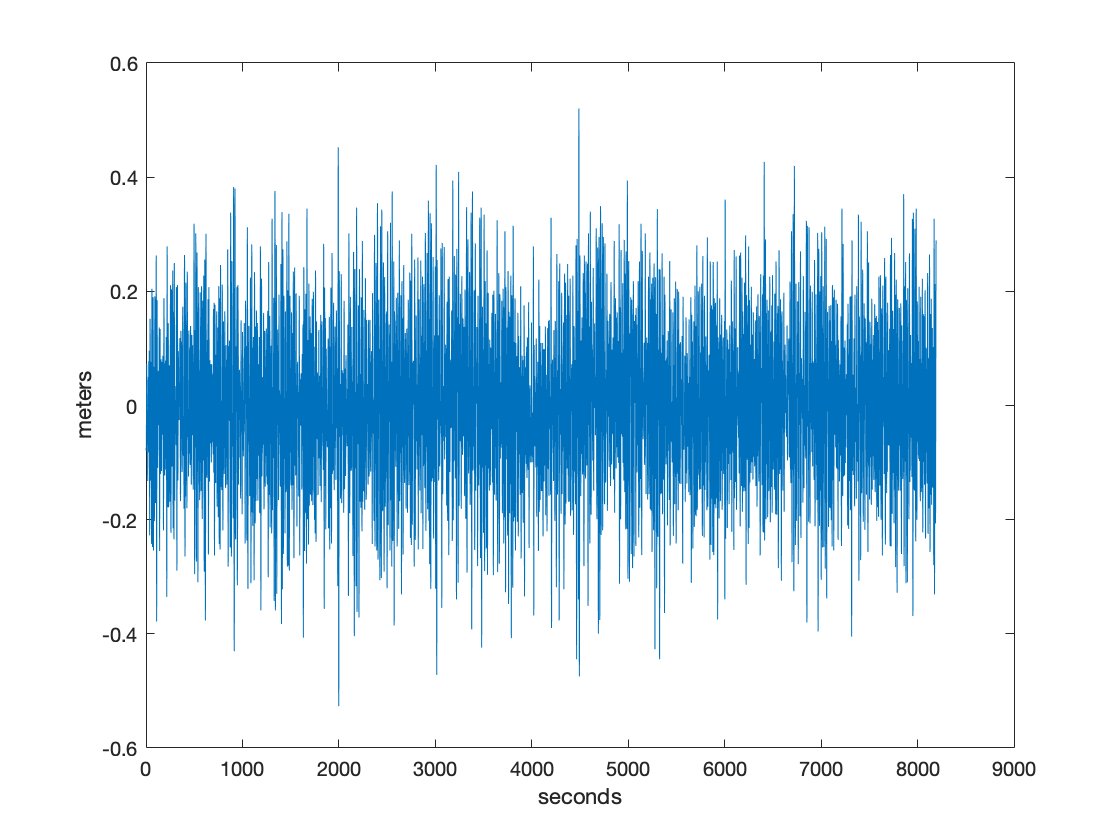

load Wave_elevation.mat
figure (1)
clf
plot(t,e)
ylabel('meters')
xlabel('seconds')

## Histogram showing counts in each bin.

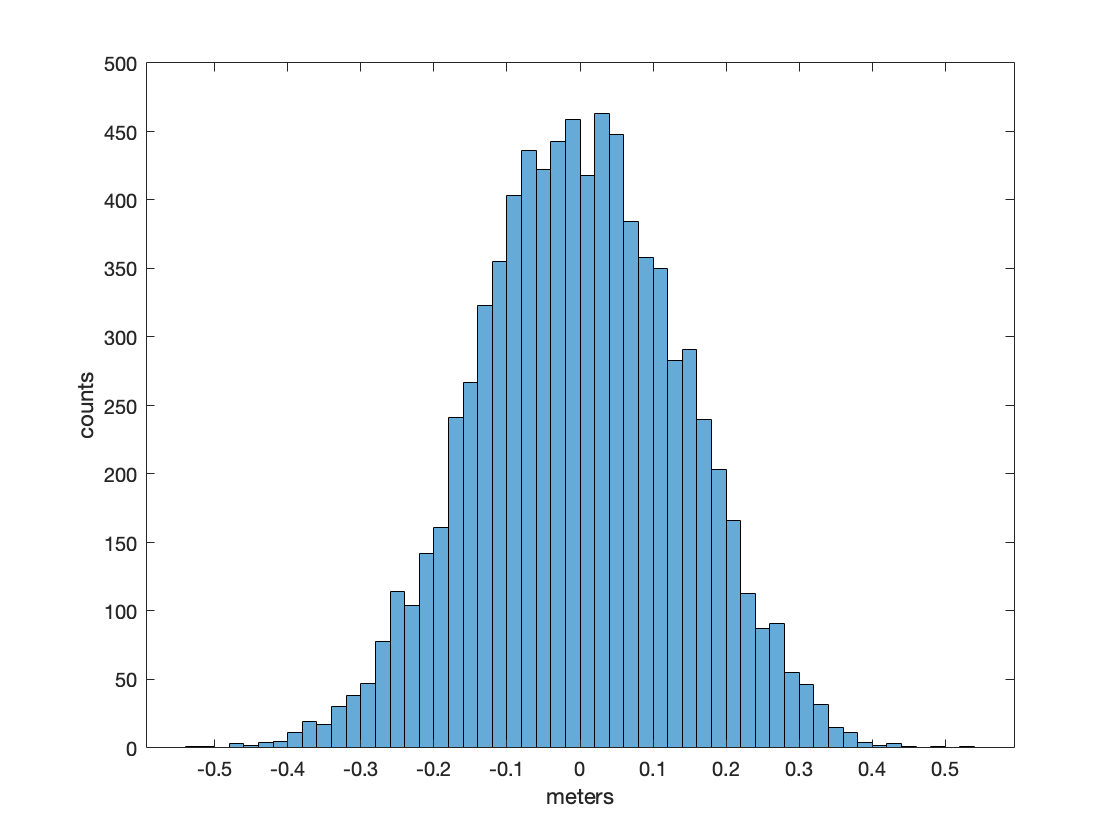

figure (2)
clf
histogram(e)
xlabel('meters')
ylabel('counts') 

## Histogram showing probability, counts divided by total number of points

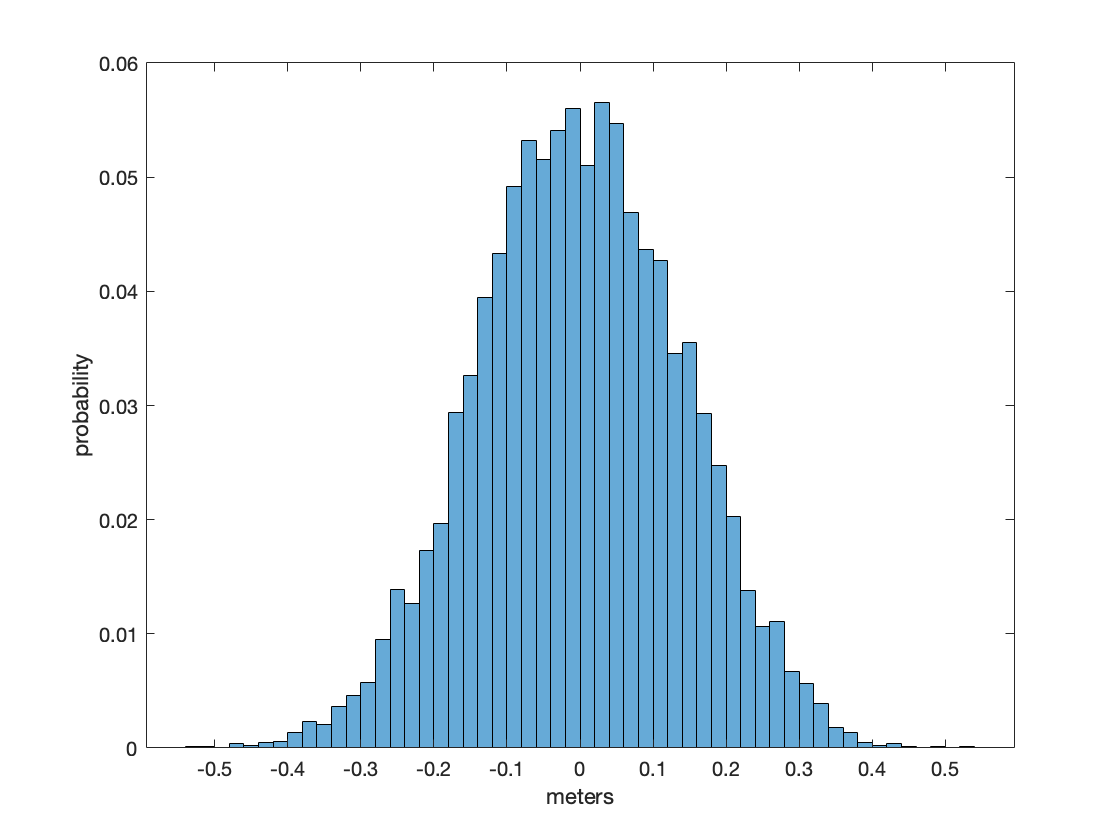

figure (3)
clf
histogram(e,'Normalization','probability')
xlabel('meters')
ylabel('probability') 

## Show that probability changes as bin size changes

Change number of bins to 100

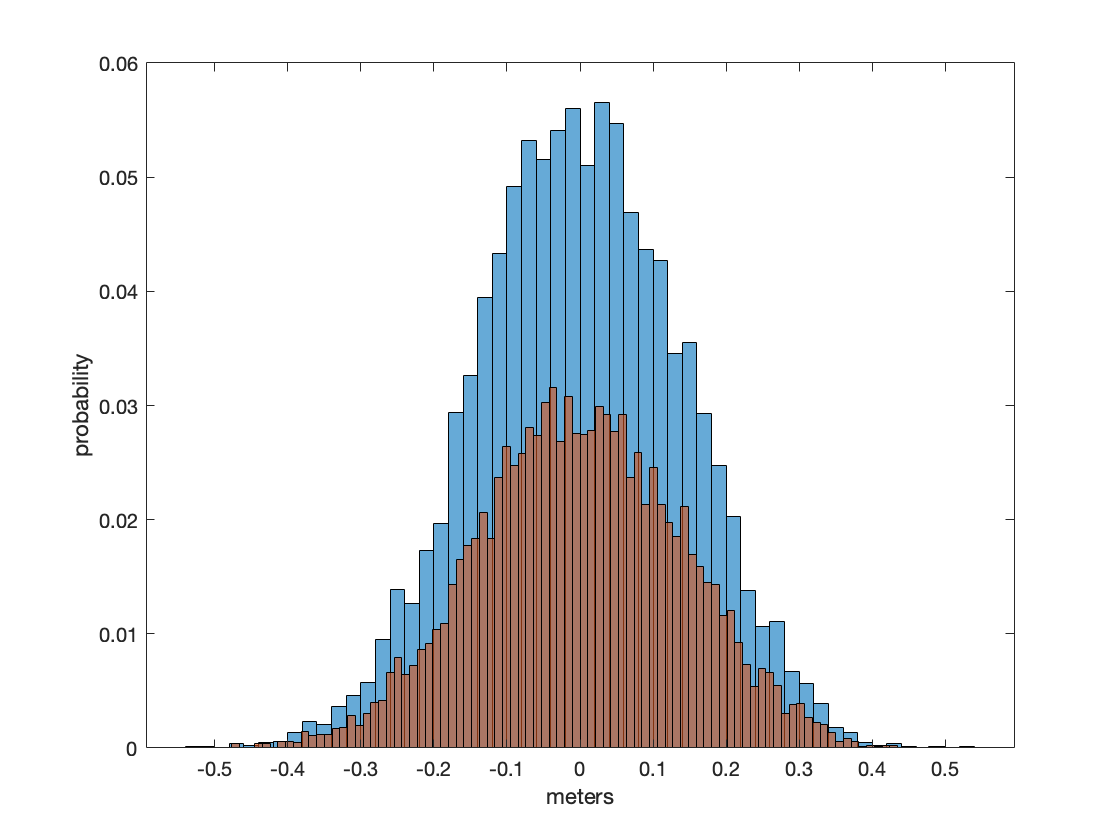

hold on
histogram(e,100,'Normalization','probability')
hold off

## Plot a PDF = probability / bin width

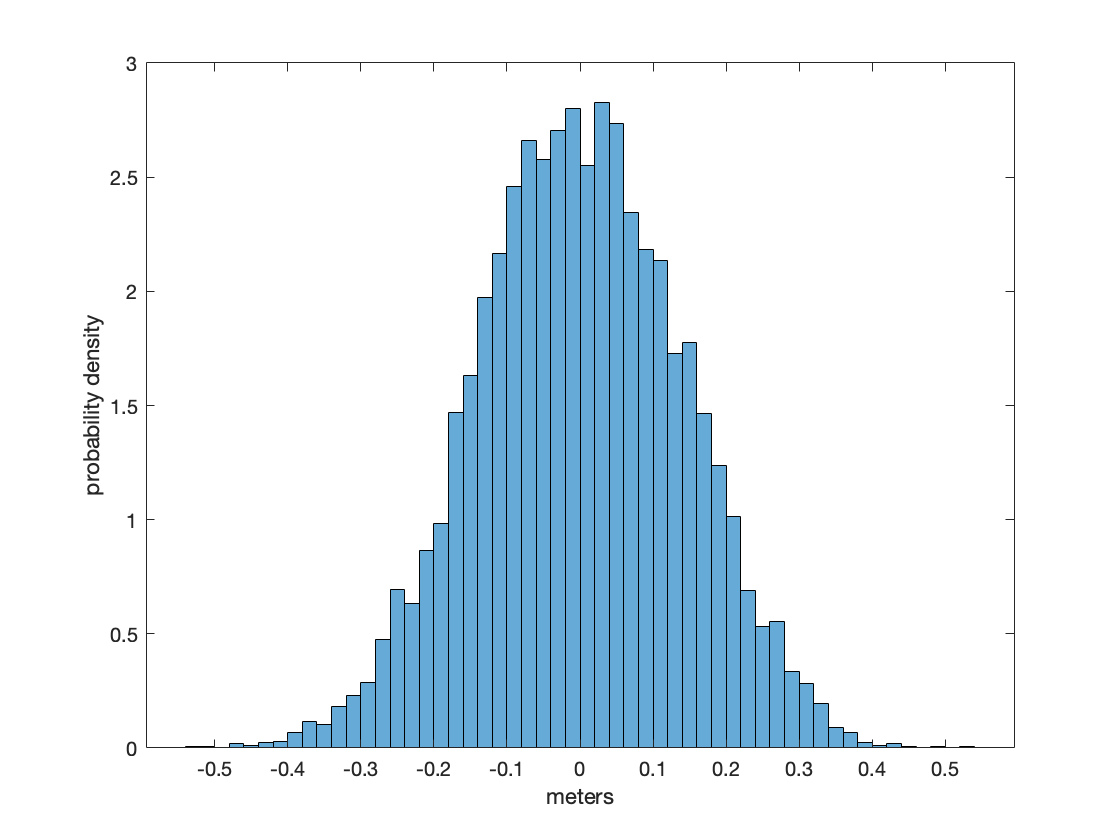

figure (4)
clf
histogram(e,'Normalization','pdf')
xlabel('meters')
ylabel('probability density') 

Change number of bins

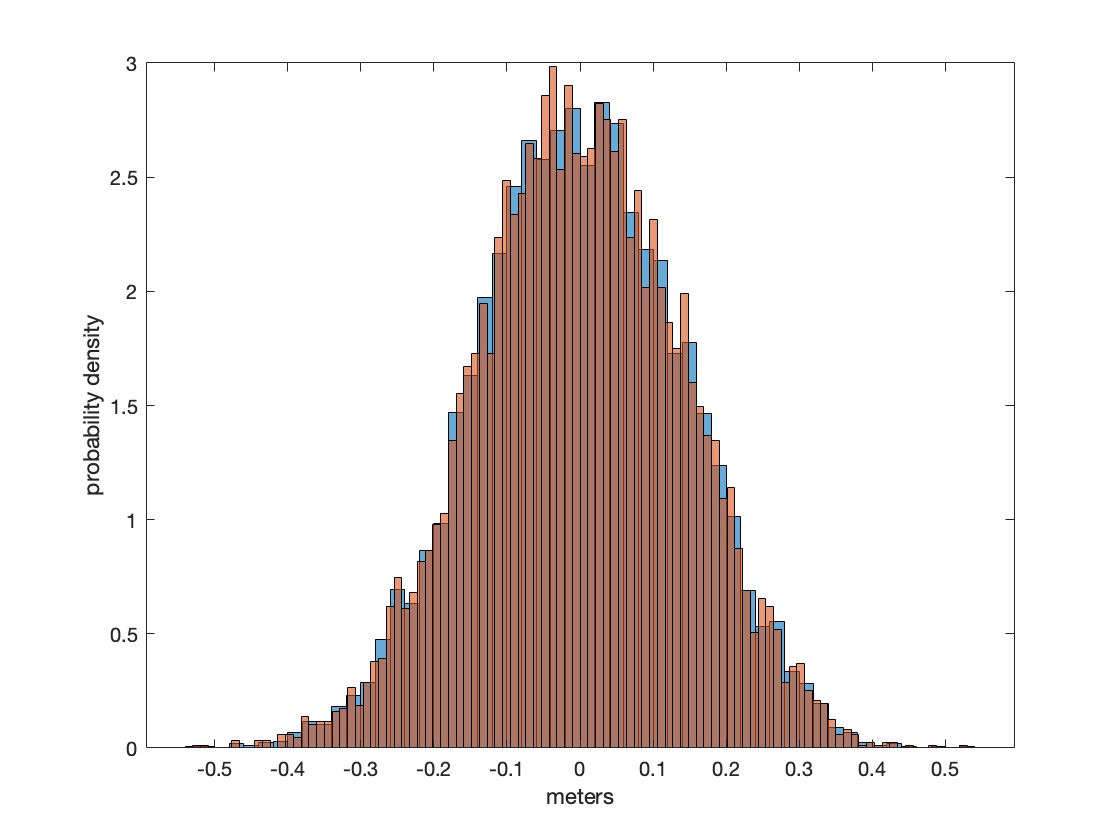

hold on
histogram(e,100,'Normalization','pdf')

PDF does not depend on bin size

## Compare to a Gaussian distribution

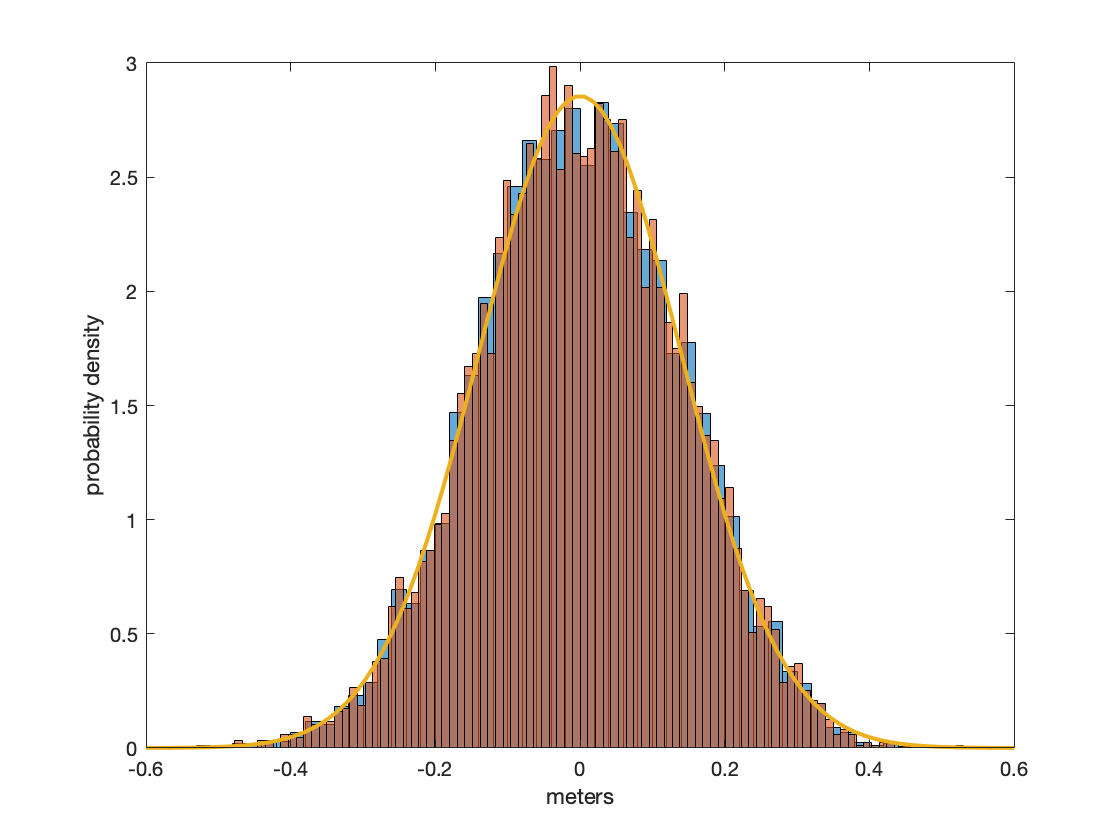

x = linspace(-.6,.6,100);
P = normpdf(x,mean(e),std(e));
plot(x,P,'LineWidth',2)

## Cumulative Distribution Function

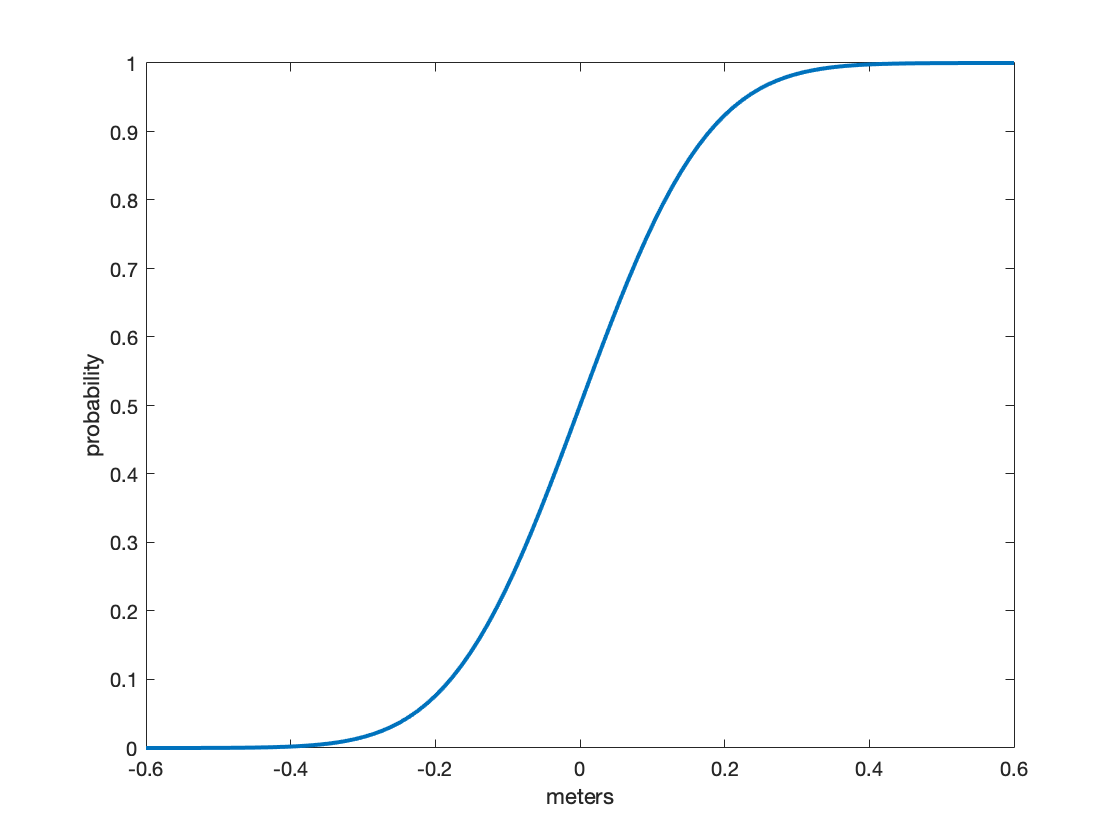

figure (6)
clf
plot(x,normcdf(x,mean(e),std(e)),'LineWidth',2)
xlabel('meters')
ylabel('probability')

## Probability  elevation > 0.3m

1-normcdf(0.3,mean(e),std(e))

ans = 0.9841

## Elevation corresponding to 98th percentile

norminv(.98,mean(e),std(e))

ans = 0.2869